clear;
clc;

set( groot, 'defaultLineLineWidth', 1.2 ) ; % plot line 두께 지정
set( groot, 'defaultAxesXGrid', 'on' ) ; % x축 방향으로 grid 생성
set( groot, 'defaultAxesYGrid', 'on' ) ; % y축 방향으로 grid 생성
set( groot, 'defaultAxesTitleFontSizeMultiplier', 1.5);  % Title 크기 설정
set( groot, 'defaultAxesFontSize', 12 ); % 축에 있는 글씨 크기 지정
set( groot, 'defaultAxesFontName', 'Times New Roman'); % 축에 있는 글씨 폰트 지정
set( groot, 'defaultFigureColor', 'w'); % figure 색상

% Load data
dateStr = '20250717';      % log date
runIdx  = '1';             % log nums

scriptFullPath = matlab.desktop.editor.getActiveFilename;
currentDir = fileparts(scriptFullPath);

while true
    [parentDir, folderName] = fileparts(currentDir);
    if strcmp(folderName, 'mppi_solver')
        projectRoot = currentDir;
        break;
    end
    if isempty(parentDir)
        error('Directory mppi_solver not found');
    end
    currentDir = parentDir;
end

absPath = fullfile(projectRoot, 'runs', ...
                   dateStr, runIdx, 'mppi_canadarm');

ee_pose = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/end_effector_pose');
pos_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/pos_err');
ori_err = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/ori_err');
cost    = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/cost');
sigma   = h5read(fullfile(absPath, 'end_effector_pose.mat'), '/sigma');

clearvars dateStr runIdx scriptFullPath currentDir parentDir folderName projectRoot absPath

init_data_idx = 1;
ee_pose = ee_pose(:,init_data_idx:end);
pos_err = pos_err(:,init_data_idx:end);
ori_err = ori_err(:,init_data_idx:end);
cost    = cost(:,init_data_idx:end);
sigma   = sigma(:,init_data_idx:end);

ee_pose(1,:) = ee_pose(1,:) - ee_pose(1,1);
pos_err(1,:) = pos_err(1,:) - pos_err(1,1);
ori_err(1,:) = ori_err(1,:) - ori_err(1,1);
cost(1,:)    = cost(1,:)    - cost(1,1);
sigma(1,:)   = sigma(1,:)   - sigma(1,1);

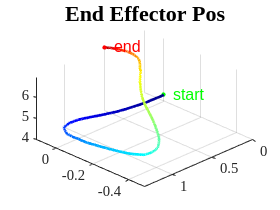

sim_time_ee_pose = ee_pose(1,:);
ee_pos = ee_pose(2:4,:);
ee_ori = ee_pose(5:7,:);

N = size(ee_pos,2);

figure;
hold on;
colormap(jet(N-1));
cmap = jet(N-1);

for k = 1:N-1
    plot3( ...
      ee_pos(1,k:k+1), ee_pos(2,k:k+1), ee_pos(3,k:k+1), ...
      'Color', cmap(k,:), ...
      'LineWidth', 2 );
end

plot3(ee_pos(1,1), ee_pos(2,1), ee_pos(3,1), 'go', 'MarkerFaceColor','g', 'MarkerSize',2);
text(ee_pos(1,1), ee_pos(2,1), ee_pos(3,1), '  start', 'FontSize',12, 'Color','g');

plot3(ee_pos(1,end), ee_pos(2,end), ee_pos(3,end), 'ro', 'MarkerFaceColor','r', 'MarkerSize',2);
text(ee_pos(1,end), ee_pos(2,end), ee_pos(3,end), '  end', 'FontSize',12, 'Color','r');
hold off;
title("End Effector Pos")
view([-1 1 1.5]);

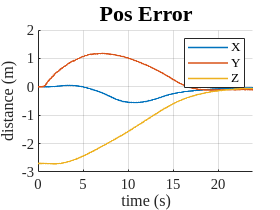

sim_time_pos_err = pos_err(1,:);

figure;
hold on
plot(sim_time_pos_err, pos_err(2,:));
plot(sim_time_pos_err, pos_err(3,:));
plot(sim_time_pos_err, pos_err(4,:));
hold off
title("Pos Error")
xlabel("time (s)")
ylabel("distance (m)")
legend("X","Y","Z")

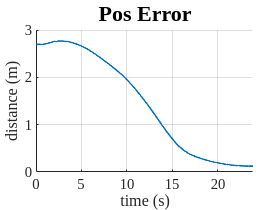


err_dist = vecnorm(pos_err(2:4,:));

figure;
hold on
plot(sim_time_pos_err, err_dist);
hold off
title("Pos Error")
xlabel("time (s)")
ylabel("distance (m)")

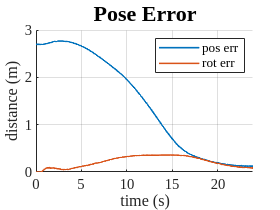


ori_err_dist = vecnorm(ori_err(2:4,:));

figure;
hold on
plot(sim_time_pos_err, err_dist);
plot(sim_time_pos_err, ori_err_dist);
hold off
title("Pose Error")
xlabel("time (s)")
ylabel("distance (m)")
legend('pos err', 'rot err')

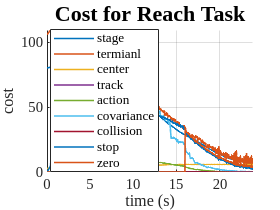

sim_time_cost   = cost(1,:);
stage_cost      = cost(2,:);
terminal_cost   = cost(3,:);
centering_cost  = cost(4,:);
tracking_cost   = cost(5,:);
action_cost     = cost(6,:);
covar_cost      = cost(7,:);
collision_cost  = cost(8,:);
stop_cost       = cost(9,:);
zero_cost       = cost(10,:);

figure;
hold on
plot(sim_time_cost, stage_cost);
plot(sim_time_cost, terminal_cost);
plot(sim_time_cost, centering_cost);
plot(sim_time_cost, tracking_cost);
plot(sim_time_cost, action_cost);
plot(sim_time_cost, covar_cost);
plot(sim_time_cost, collision_cost);
plot(sim_time_cost, stop_cost);
plot(sim_time_cost, zero_cost);
hold off
title("Cost for Reach Task")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "center", "track", "action", "covariance", "collision", "stop", "zero", "Location","best")

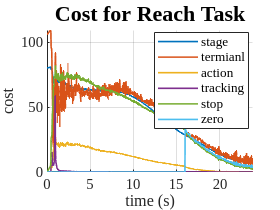


figure;
hold on
plot(sim_time_cost, stage_cost);
plot(sim_time_cost, terminal_cost);
plot(sim_time_cost, action_cost);
plot(sim_time_cost, tracking_cost);
plot(sim_time_cost, stop_cost);
plot(sim_time_cost, zero_cost);
hold off
title("Cost for Reach Task")
xlabel("time (s)")
ylabel("cost")
legend("stage", "termianl", "action", "tracking", "stop", "zero", "Location","best")

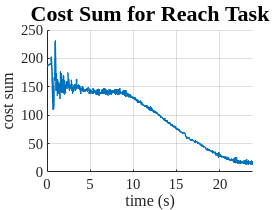



reach_cost_sum = stage_cost + terminal_cost + centering_cost + ...
                 tracking_cost + action_cost + covar_cost;

reach_cost_sum = stage_cost + terminal_cost + tracking_cost + action_cost;

figure;
hold on
plot(sim_time_cost, reach_cost_sum);
hold off
title("Cost Sum for Reach Task")
xlabel("time (s)")
ylabel("cost sum")

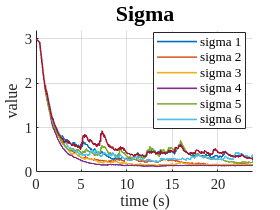

sim_time_sigma = sigma(1,:);
sigma_value    = sigma(2:end,:);

figure;
hold on
plot(sim_time_sigma, sigma_value);
hold off
title("Sigma")
xlabel("time (s)")
ylabel("value")
ylim([0 3.2])
legend("sigma 1", "sigma 2", "sigma 3", "sigma 4", "sigma 5", "sigma 6", "Location","best")